clear all

% Read it
report = readmatrix("Satellite-Satellite1-Antenna-Antenna29-To-Facility-AntarcticaTrollsat_Access.csv")

report = 	1.0e+06 *

    0.0000    0.0256    0.0258    0.0003
    0.0000    0.0311    0.0317    0.0006
    0.0000    0.0369    0.0375    0.0006
    0.0000    0.0427    0.0433    0.0006
    0.0000    0.0485    0.0491    0.0006
    0.0000    0.0543    0.0549    0.0006
    0.0000    0.0601    0.0605    0.0004
    0.0000    0.1144    0.1149    0.0005
    0.0000    0.1201    0.1207    0.0006
    0.0000    0.1259    0.1265    0.0006


numstations = 24;

% Remove header rows
for i = 1:length(report)-numstations
    if isnan(report(i,1))
        
        report(i,:) = [];
        
    end
end

% Remove first column
report(:,[1]) = [];

%number of separate accesses to the stations
accesses = length(report);

for i = 1:accesses
    
    %make column for which orbit number each access occurs in
    orbitnum(i,1) = round(report(i,1)/(60*90));
    
end

report = [orbitnum,report];

%repeat for each orbit
for i = 0:max(orbitnum)
    currentorbit = [];
    m = 1;
    
    for j = 1:accesses
        
        if report(j,1) == i
            
            %create array for all access in a single orbit
            currentorbit(m,1) = report(j,4);
            m = m+1;
            
        end
        
    end
    
    %find the max and min in the single orbit and make array of all max and
    %min found
    minduration(i+1,1) = min(currentorbit);
    maxduration(i+1,1) = max(currentorbit);
    
    %a list from 1 to the number of orbits that happen
    orbit(i+1,1) = i;
    
end

%matrix of shortest and longest access time in each orbit
minmaxduration1 = [orbit,minduration,maxduration]

minmaxduration1 =          0   38.5720  582.4150
    1.0000  370.4320  617.1830
    2.0000  227.8980  638.2510
    3.0000  106.0680  643.8030
    4.0000  233.3470  641.5710
    5.0000  164.5510  638.0120
    6.0000  239.0440  635.5180
    7.0000  146.6060  643.4780
    8.0000  137.6620  635.2230
    9.0000  218.6420  639.6390



%minimum transmission time required
mintimeneeded = 134.8;

%check to make sure we have at least 1 access period long enough in each
%orbit
for i = 1:length(minmaxduration1)
    
    if minmaxduration1(i,3) < mintimeneeded
        
        failure(i,1) = 1;
        fprintf('rip')
        
    else
        
        failure(i,1) = 0;
        
    end
    
end

failure

failure =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


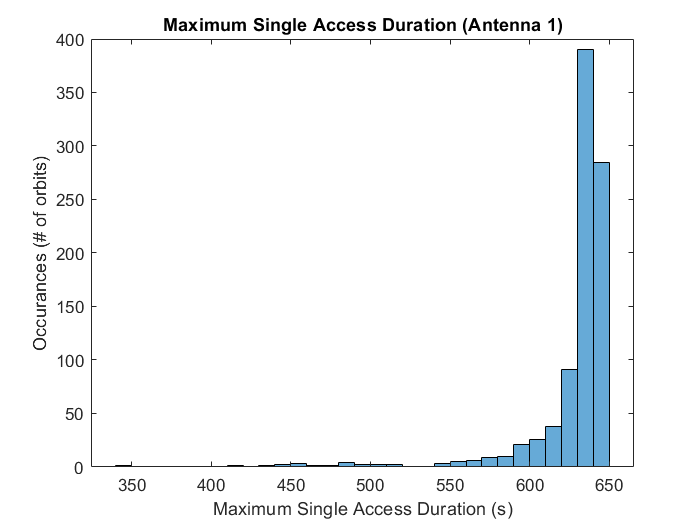


%create histogram of max durations
figure(1)
histogram(minmaxduration1(:,3))
xlabel('Maximum Single Access Duration (s)')
ylabel('Occurances (# of orbits)')
title('Maximum Single Access Duration (Antenna 1)')


%-----------------------------------------------------------------------------------
%Repeat whole thing for second antenna
report = readmatrix("Satellite-Satellite1-Antenna-Antenna30-To-Facility-AntarcticaTrollsat_Access.csv")

report = 	1.0e+06 *

    0.0000    0.0256    0.0258    0.0003
    0.0000    0.0311    0.0317    0.0006
    0.0000    0.0369    0.0375    0.0006
    0.0000    0.0427    0.0433    0.0006
    0.0000    0.0485    0.0491    0.0006
    0.0000    0.0543    0.0549    0.0006
    0.0000    0.0601    0.0605    0.0004
    0.0000    0.1144    0.1149    0.0005
    0.0000    0.1201    0.1207    0.0006
    0.0000    0.1259    0.1265    0.0006


numstations = 24;

for i = 1:length(report)-numstations
    if isnan(report(i,1))
        
        report(i,:) = [];
        
    end
end

report(:,[1]) = [];

accesses = length(report);

for i = 1:accesses
    
    orbitnum(i,1) = round(report(i,1)/(60*90));
    
end

report = [orbitnum,report];

for i = 0:max(orbitnum)
    currentorbit = [];
    m = 1;
    
    for j = 1:accesses
        
        if report(j,1) == i
            
            currentorbit(m,1) = report(j,4);
            m = m+1;
            
        end
        
    end
    
    orbit(i+1,1) = i;
    minduration(i+1,1) = min(currentorbit);
    maxduration(i+1,1) = max(currentorbit);
    
end

minmaxduration2 = [orbit,minduration,maxduration]

minmaxduration2 =          0   38.5720  582.4150
    1.0000  370.4320  617.1830
    2.0000  227.8980  638.2510
    3.0000  106.0680  643.8030
    4.0000  233.3470  641.5710
    5.0000  164.5510  638.0120
    6.0000  239.0440  635.5180
    7.0000  146.6060  643.4780
    8.0000  137.6620  635.2230
    9.0000  218.6420  639.6390



for i = 1:length(minmaxduration2)
    
    if minmaxduration2(i,3) < mintimeneeded
        
        failure(i,1) = 1;
        fprintf('rip')
        
    else
        
        failure(i,1) = 0;
        
    end
    
end

failure

failure =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


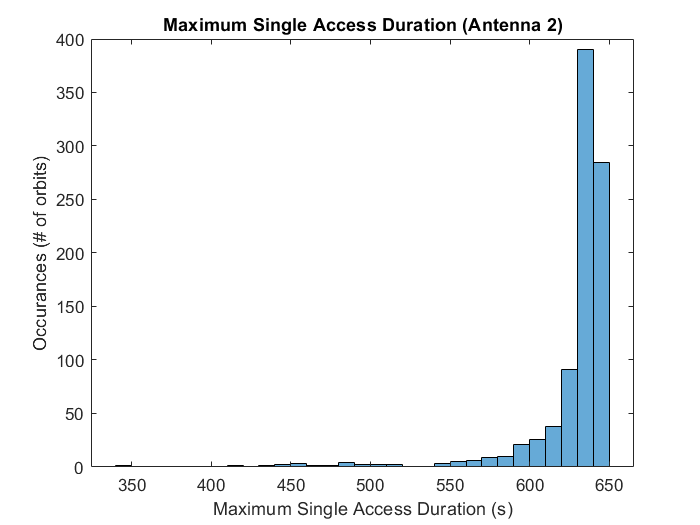


figure(2)
histogram(minmaxduration2(:,3))
xlabel('Maximum Single Access Duration (s)')
ylabel('Occurances (# of orbits)')
title('Maximum Single Access Duration (Antenna 2)')

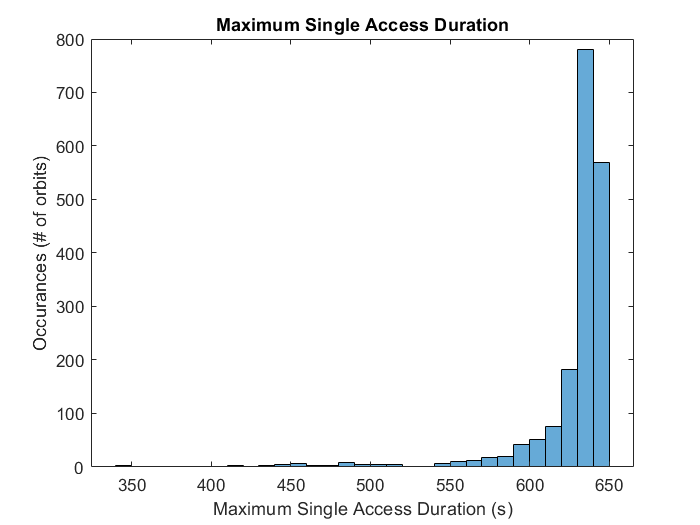

%-----------------------------------------------------------------------------------


%single hist. for both antennae
figure(3)
histogram([minmaxduration1(:,3),minmaxduration2(:,3)])
xlabel('Maximum Single Access Duration (s)')
ylabel('Occurances (# of orbits)')
title('Maximum Single Access Duration')

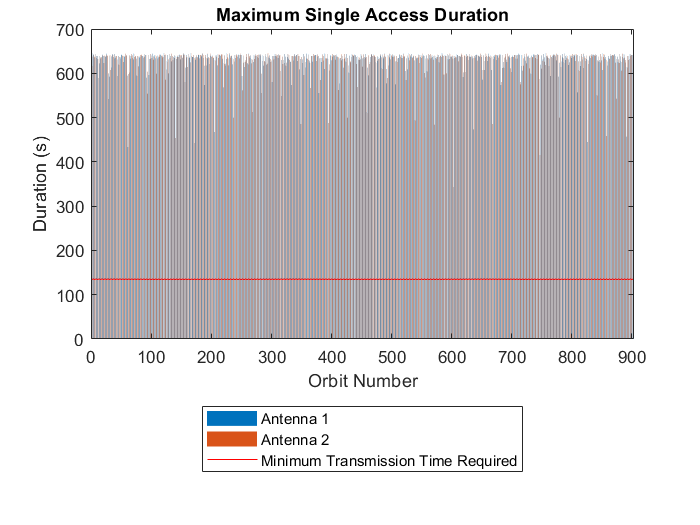


%bar graph in case that shows it better
figure(4)
bar([minmaxduration1(:,1),minmaxduration2(:,1)],[minmaxduration1(:,3),minmaxduration2(:,3)],'BarWidth',1)
hold on
plot(xlim,[mintimeneeded mintimeneeded], 'r')
legend('Antenna 1','Antenna 2','Minimum Transmission Time Required','Location','southoutside')
xlabel('Orbit Number')
ylabel('Duration (s)')
title('Maximum Single Access Duration')
hold off